## Load the Data and place into seperate containers

load exp1.mat 
time = exp1.X.Data;
vel_motor = exp1.Y(1).Data;
vel_table = exp1.Y(2).Data;
voltage = exp1.Y(3).Data;

## Plot for visualization

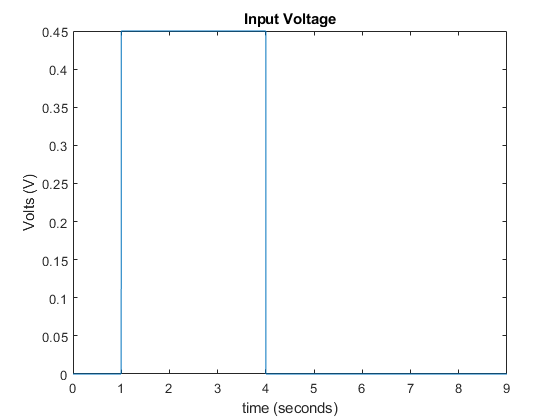

plot(time,voltage)
title('Input Voltage')
ylabel('Volts (V)')
xlabel('time (seconds)')

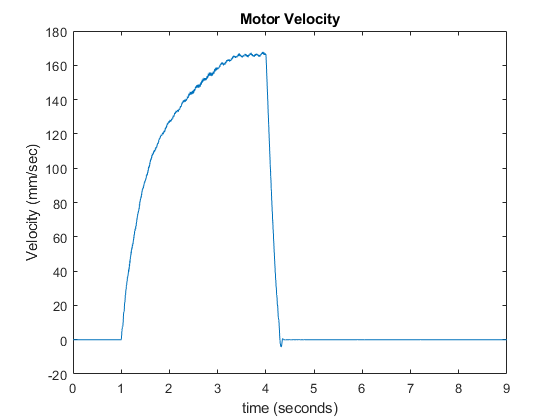


plot(time,vel_motor)
title('Motor Velocity')
ylabel('Velocity (mm/sec)')
xlabel('time (seconds)')

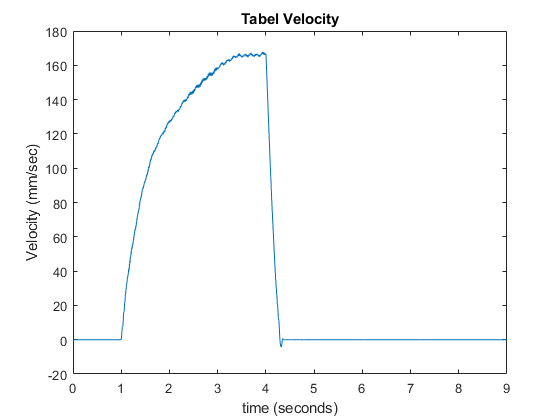


plot(time,vel_motor)
title('Tabel Velocity')
ylabel('Velocity (mm/sec)')
xlabel('time (seconds)')

## Find the max Table Velocity and Time Constant $\tau_m$

max_table_vel = max(vel_table);
step_voltage_value = max(voltage);

%We know $\tau_m$ is is the time where the velocity reaches 63% of the final value
% The 1:4000 is to prevent finding a time on the slowdown edge
[minValue, closestIndex] = min(abs(vel_table(1:4000)-0.63*max_table_vel));
tau_m = time(closestIndex)

tau_m = 1.6770

## Fine $B_e$ and $J_e$

% From the final value theorem we know V_input/Be = max_table_vel
Be = step_voltage_value/max_table_vel

Be = 0.0027


%tau_m = Je/Be
Je = tau_m * Be

Je = 0.0044